clear
close all

nElem = 3;
eDegree = 2;
continuity = eDegree - 1;
contVector = [-1 continuity*ones(1,nElem-1) -1];


%%
L = 1;
base = 0.005;
height = 0.005;
E = 1e6;
poissonRatio = 0.29;
syms f(x)
f(x) = [0; ...
        0; ...
        10*height^3; ...
        0;...
        0;...
        0]

$$f(x) = \left(\begin{array}{c} 0\\ 0\\ \frac{2951479051793529}{2361183241434822606848}\\ 0\\ 0\\ 0 \end{array}\right)$$

    
shearCorrection = "no";

%% Define BC
% Fixed - Free 
BC.U.location = [x == 0];
BC.U.val = [0];

BC.V.location = [x == 0];
BC.V.val = [0];

BC.W.location = [x == 0];
BC.W.val = [0];

BC.Theta1.location = [x == 0];
BC.Theta1.val = [0];

BC.Theta2.location = [x == 0];
BC.Theta2.val = [0];

BC.Theta3.location = [x == 0];
BC.Theta3.val = [0];




feSolution = main(nElem,eDegree,contVector,f,BC,base,height,E,poissonRatio,shearCorrection);

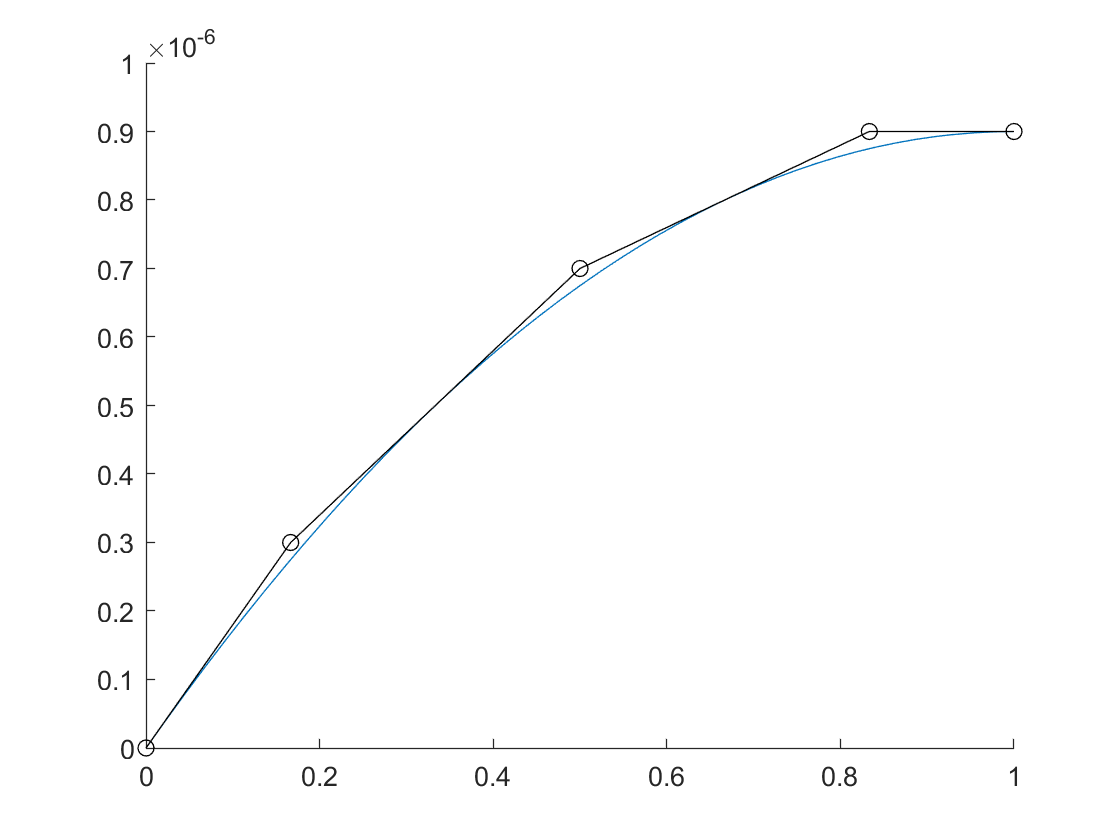


I = 1/12 * base * height^3;
G = E / (2*(1+poissonRatio));
A = base*height;
k = 1;

conditions = [0, 0, 0;...
              1, 0, 0;...
              2, 0, 0;...
              3, 0, 0];

f = formula(f);
exactSolution = computeExactSolution(1,E,I,k,A,G,f(3),conditions);

figure
hold on

% fplot(exactSolution.U,[0 1])
U = formula(feSolution.U);
fplot(U(3),[0 1])
plot(feSolution.Spline.nodes, feSolution.LinearSystem.d(3:6:end),'-ko')